# Combine Time Domain and Frequency Domain

clear;
total_subjects = 29;
for i=1:total_subjects
    subject = i;

    if subject < 10
        sujeto = strcat('S0',num2str(subject-1));
    elseif subject > 10
        sujeto = strcat('S',num2str(subject-1));
    end

    X_1 = load(strcat(sujeto,'\',sujeto,'X_1.mat'));
    X_1 = X_1.X_1;
    X_2 = load(strcat(sujeto,'\',sujeto,'X_2.mat'));
    X_2 = X_2.X_2;
    y = load(strcat(sujeto,'\',sujeto,'y.mat'));
    y = y.y;

    X = cat(2,X_1,X_2);

    savelocation = strcat('All_TD_FD','/',sujeto,'Xcomb.mat');
    save(savelocation,"X");
end

## Train with TD-FD

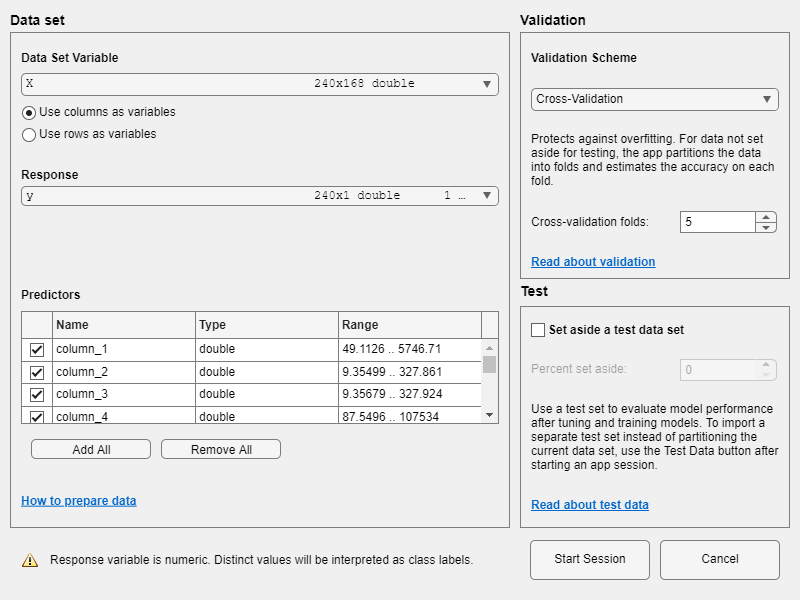

% classificationLearner(X,y,"CrossVal","on",KFold=5)

clear;
subject = 0; % does not change
total_subjects = 29;
% x_all must be 6960x48
% y_all must be 6960x1

x_all = [];
y_all = [];

for i=1:total_subjects

    % Create paths per subject
    if(subject < 10)
        location = strcat('S0',num2str(subject));
    elseif(subject >= 10)
        location = strcat('S',num2str(subject));
    end

    % Check if location in folder exists
    if exist(location,'dir')
        % Load X and y matrix
        matx = load(strcat('All_TD_FD','/',location,'Xcomb.mat'));
        maty = load(strcat(location,'/',location,'y.mat'));

        % Concatenate to matrix
        x_all = cat(1,x_all,matx.X(:,:));
        y_all = cat(1,y_all,maty.y(:,:));

    end

    subject = subject + 1;
end

## Train all and test with 1

alone = 2; % Change value depending on subject
fprintf('Subject S%i\n',alone-1)

Subject S1



% Normalize
x_all = (x_all)./(x_all).^2;

% Get testing matrix ALONE
x_test(:,:) = x_all((alone*240-239:alone*240),:);
y_test(:,:) = y_all((alone*240-239:alone*240));

% Get training matrix ALL
x_train = x_all;
x_train((alone*240-239:alone*240),:) = [];
y_train = y_all;
y_train((alone*240-239:alone*240)) = [];

if alone < 10
    sujeto = strcat('S0',num2str(alone-1));
elseif alone >= 10
    sujeto = strcat('S0',num2str(alone-1));
end


## Train with TD-FD

classificationLearner(x_train,y_train,"CrossVal","on",KFold=5)
return

## Testing combined matrix

true = 0;
g1 = zeros(1,240);
g2 = zeros(1,240);
acc = 0;

for i=1:240
    yfit = model.predictFcn((x_test(i,:)));

    if(i <= 40)
        g1(i) = 1;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>40 && i<=80)
        g1(i) = 2;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>80 && i<=120)
        g1(i) = 3;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>120 && i<=160)
        g1(i) = 4;
        g2(i) = yfit;g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>160 && i<=200)
        g1(i) = 5;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>200)
        g1(i) = 6;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    end

end

acc = true/240;
fprintf('Test accuracy %2f\n',acc)

Test accuracy 0.175000


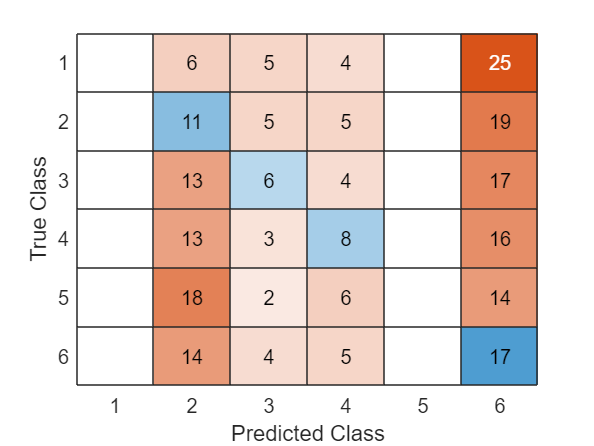

C = confusionmat(g1,g2);

figure;
confusionchart(C)